clc;
clear all;

% Threshold for scratch out (percentage of answer region)
scratchedThresh = .7;

%Number of corners + boolean for answer
numOfParameters = 6;

%How many choices the test taker has
numOfOptions = 4;

%Bounding box threshhold for answer 
%(how high circle has to be to be marked as an answer)
answerThresh = 40;

%Threshhold to find red marks
bwThresh = .49;





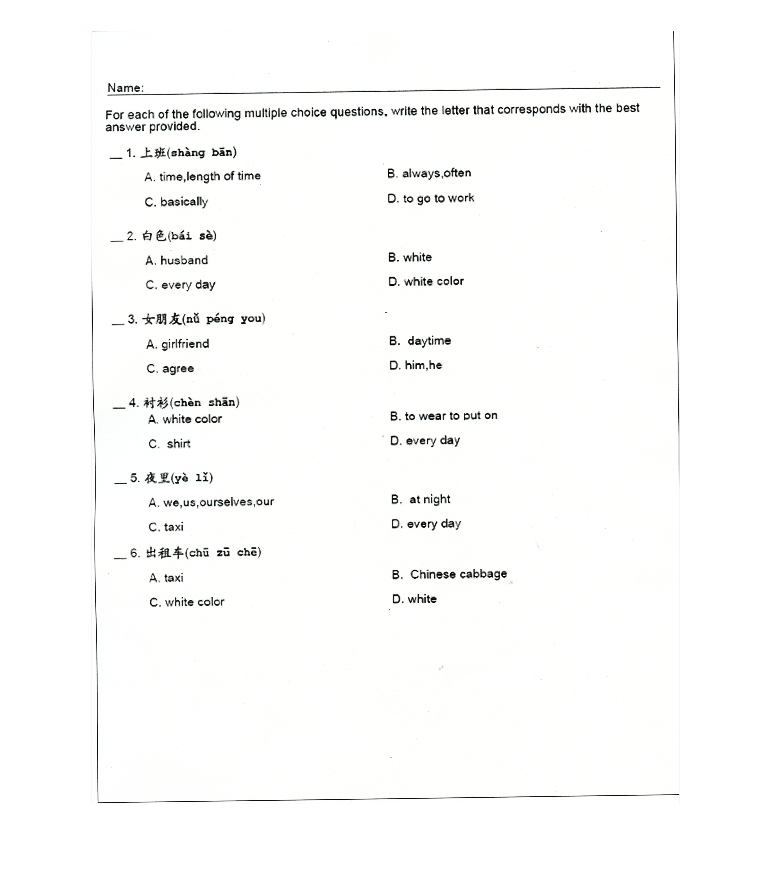

%Take in answer key

% Blank
I1 = imread('b.jpg');
% Answer
I2 = imread ('a.jpg');
% Student
% I3 = imread ('s.jpg');
I3 = imread ('s.jpg');


figure;imshow(I1);title('Blank Test');

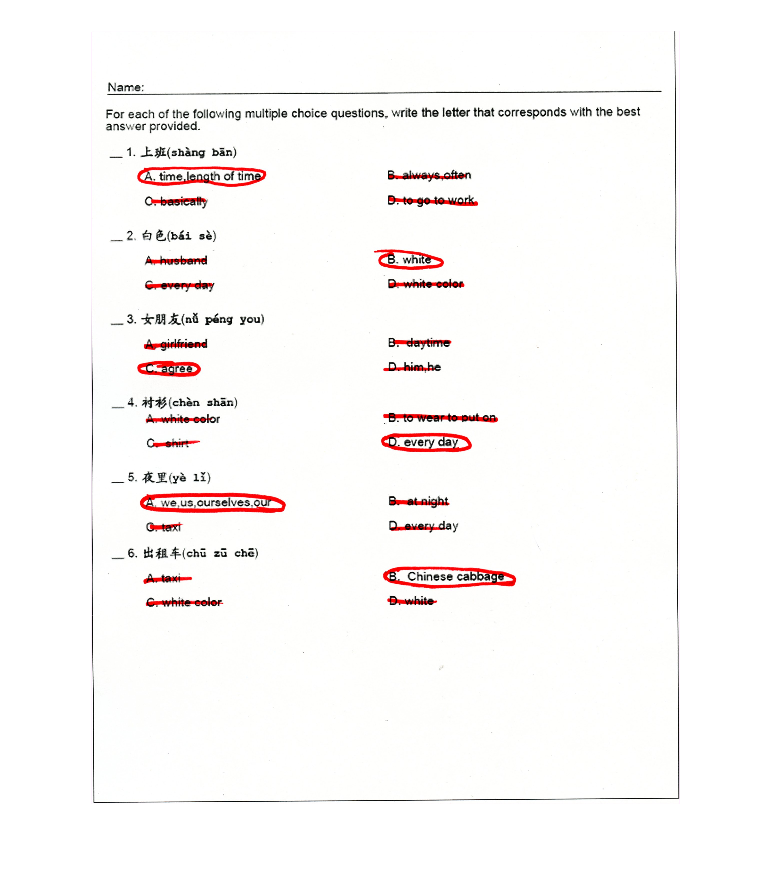

figure;imshow(I2);title('Answer key');

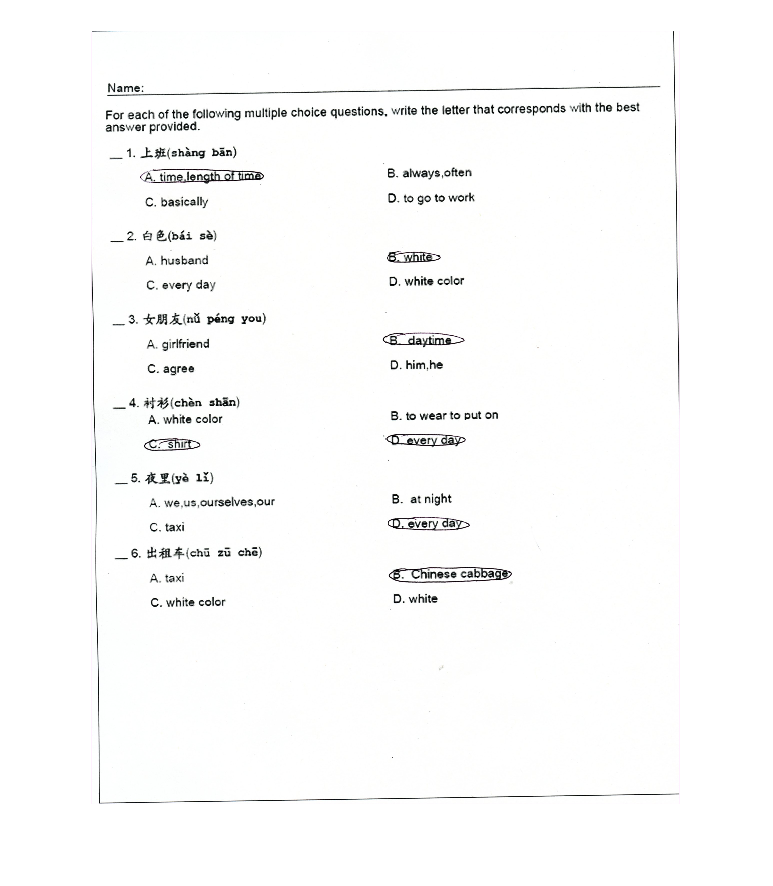

figure;imshow(I3);title('Student Answers');

% Make images same size and orientation

% I1 = testHarris(I1);
% I2 = testHarris(I2);
% I3 = testHarris(I3);
% 
% figure;imshow(I1);title('test Harris Output');text(0,0,'test');





%Size to pad bounding boxes and also image by
extraSizeAmount = 15;

I1 = padarray(I1,extraSizeAmount+1);
I2 = padarray(I2,extraSizeAmount+1);
I3 = padarray(I3,extraSizeAmount+1);

% Blank, Answer Key, Student Answers
% Rotate by 90 degrees 
B = rot90(I1);
A = rot90(I2);
S = rot90(I3);

B = im2bw(B,.6);
S = im2bw(S,.6);

D = imabsdiff(B,S);

% imshow(D);




%% Generate answer key


%Get red and green channels
RED = A(:,:,1);
GREEN = A(:,:,2);

%Get only the red marks
I = im2bw(RED - GREEN,bwThresh);

% Close gaps to make sure lines are only detected once. 
se = strel('disk',20);
I = imclose(I,se);



figure;imshow(I);title('Answer Key');


% Get red blob regions and their properties
[L,numOfBlobs] = bwlabel(I);
props = regionprops(L, 'all');


%Print out the number of questions that we have detected
numOfQuestions= numOfBlobs/numOfOptions;
disp(strcat('Number of Questions detected ', num2str(numOfQuestions)));

Number of Questions detected 6


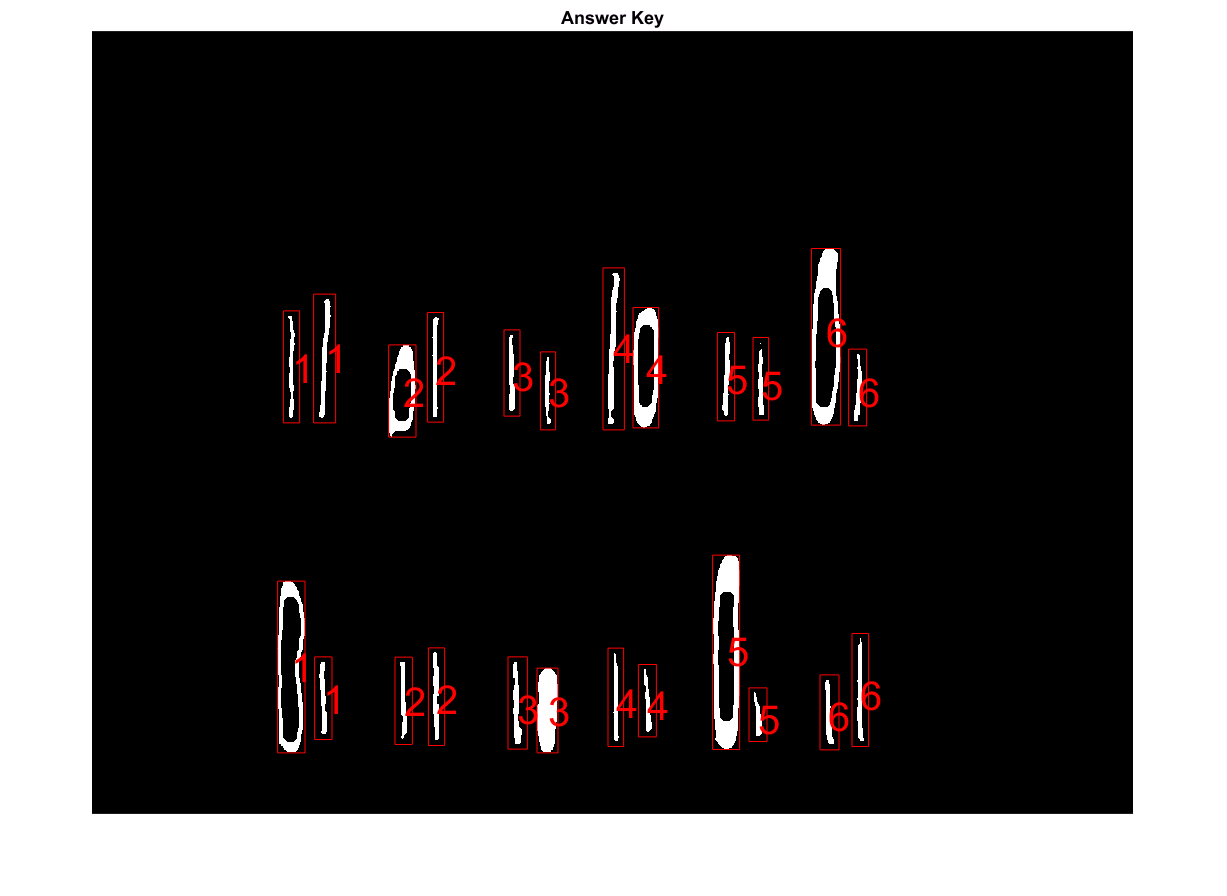



%Initalize array that will hold all questions
questionsArray = zeros(numOfOptions,numOfParameters,numOfQuestions);


%Initialize the question counter and the Question Number
optionNum = 1;
questionNum = 1;

for i=1:numOfBlobs
    % Each region is part of a Question
    if(optionNum > numOfOptions)
        optionNum = 1;
        % Increment Question number every # of options
        questionNum = questionNum +1;
    end
    
    % Get the bounding box for the option
    % Bounding box will be expanded for non-answers
    bb = props(i).BoundingBox;     
    
    % See if it is an answer and then assign a r or g
    % (note: this could also be true of false)
    isAnswer = 0;  
    if(props(i).BoundingBox(3)>answerThresh)
        isAnswer = 1;
    end    
   
    %Add parameters to array if the options are NOT ANSWERS then add additional size to region
    questionsArray(optionNum, 5, questionNum) = isAnswer;    
    
    moresize = 0;
    if(isAnswer ~= 1)
        moresize = extraSizeAmount;
    end    
    
    questionsArray(optionNum, 1, questionNum) = bb(1)- moresize;
    questionsArray(optionNum, 2, questionNum) = bb(2)- moresize;
    questionsArray(optionNum, 3, questionNum) = bb(3) + 2*moresize;
    questionsArray(optionNum, 4, questionNum) = bb(4) + 2*moresize;
    
    % Calculates the number of pixels in answer bounding box
    width = bb(3) + 2*moresize;
    height = bb(4) + 2*moresize;    
    questionsArray(optionNum, 7, questionNum) = width * height;
   
    
    % Draw Text and Bounding box
    rectangle('Position',[questionsArray(optionNum, 1, questionNum) questionsArray(optionNum, 2, questionNum) questionsArray(optionNum, 3, questionNum) questionsArray(optionNum, 4, questionNum)],'EdgeColor','r');
    text(props(i).Centroid(1),props(i).Centroid(2),num2str(questionNum),'Color','r',...
       'FontSize',24,'FontWeight','normal');
    
    %Increment option count
    optionNum = optionNum +1;     
   
 end

        
answerKey = questionsArray;
 

%% Marking Portion




%Loop through questions
for q=1:numOfQuestions
    pixelDiffArray = [];
    for o=1:numOfOptions
        pixelCount = 0;
          %questionsArray(optionNum, numOfParameters, questionNum)
        startX = round(answerKey(o, 1, q));
        startY = round(answerKey(o, 2, q));
        lenX = round(answerKey(o, 3, q));
        lenY = round(answerKey(o, 4, q));
        %loop through the image to be graded for each region
        
        % Loops through each option region           
        for l=startX:startX+lenX
            for m=startY:startY+lenY                
                    pixelCount = pixelCount + D(m,l);                                    
            end               
        end       
        pixelDiffArray = cat(1,pixelDiffArray,pixelCount);           
    end
    
    % Multiply threshold by the max amount of pixels
    thresh = scratchedThresh * answerKey(o, 7, q);    
    
    % Make a mask of values below threshold
    tfArray = pixelDiffArray < thresh;
    
    % Apply mask to the threshhold 
    pixelDiffArray = tfArray .* pixelDiffArray;
    
    
    
    % Get the max of the values that are left. 
    [M I] = max(pixelDiffArray);
    
    
    %(if parameter 6 is above zero, this is the determined answer
    answerKey(I, 6, q) = 1;
    
end
    %questionsArray(optionNum, numOfParameters, questionNum)
   
    

%Finds the number of pixels in the region on the finished student's test





% Display Results
f = figure;imshow(S);

hold on;
imrotate(S,90);

right = 0;
for q=1:numOfQuestions
    pixelDiffArray = [];
    for o=1:numOfOptions
        
        % If the Answer parameter is less than or equal to
        % the students answer parameter, then it's wrong
        a = answerKey(o, 5, q);
        s = answerKey(o, 6, q);
        if( a > 0 )
            
            if( a == s )
                disp('Answer is right!');
                right = right + 1;
            else
                disp('Answer is Wrong!');
            end
            % Draw Text and Bounding box
            
            rectangle('Position',[answerKey(o, 1, q) answerKey(o, 2, q) answerKey(o, 3, q) answerKey(o, 4, q)],'EdgeColor','g','LineWidth',4);
            
            
        end
        
        
        
    end
end

Answer is right!
Answer is right!


Answer is Wrong!


Answer is right!
Answer is right!
Answer is right!


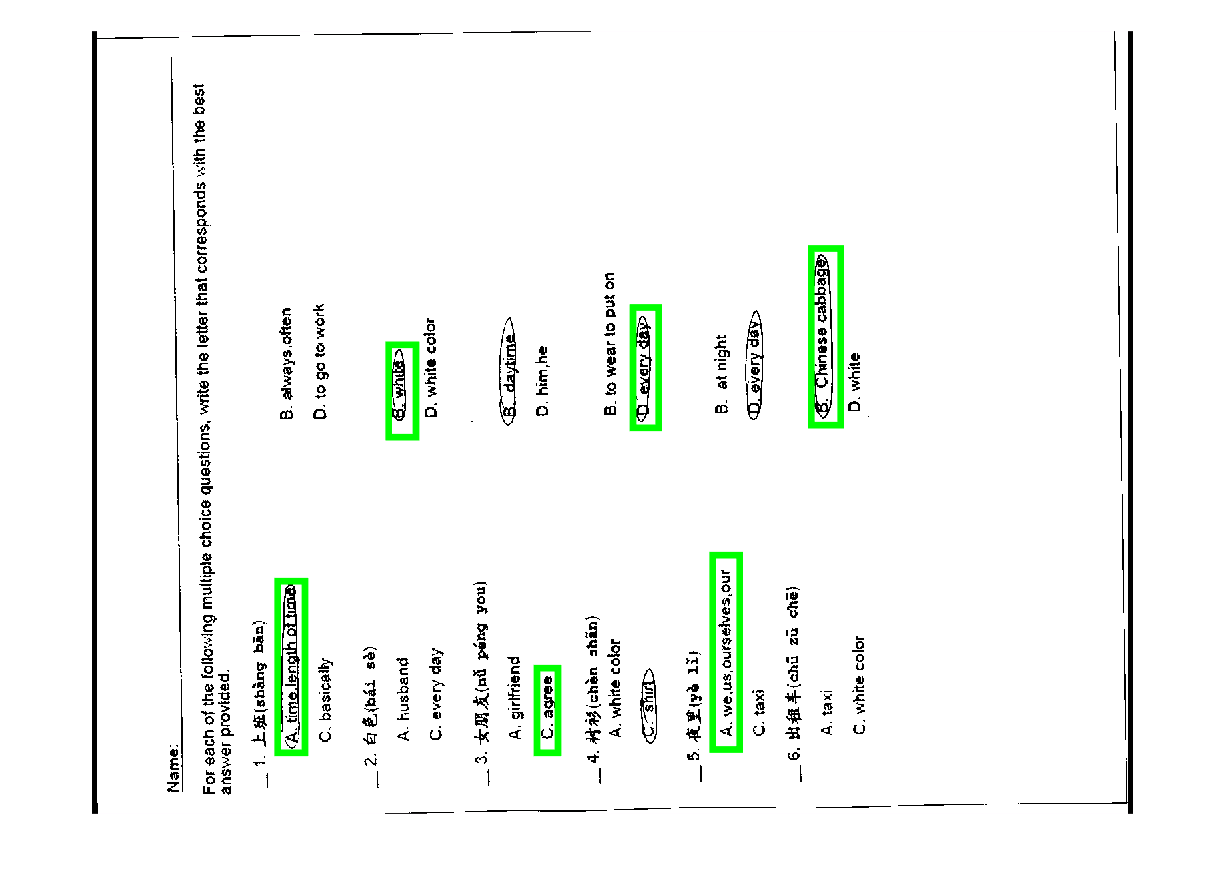




saveas(f,'testoutput.png');

save = figure;
Z = imread('testoutput.png');
H = imshow(imrotate(Z,270));

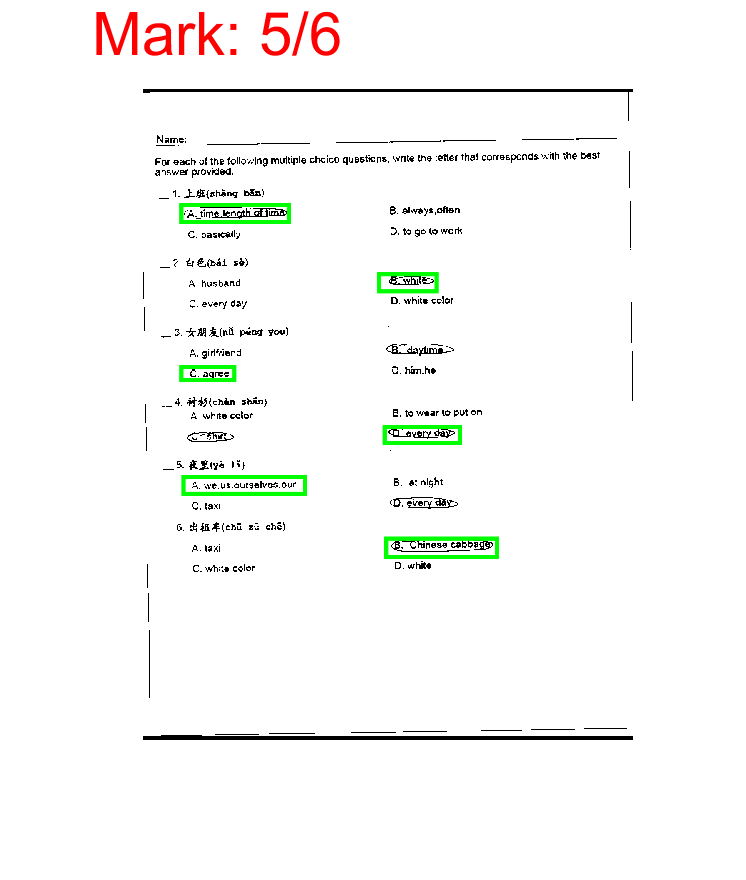

text(0,0,['Mark: ',num2str(right),'/',num2str(numOfQuestions)],'Color','r',...
       'FontSize',36,'FontWeight','normal');
saveas(save,'testoutput.png');